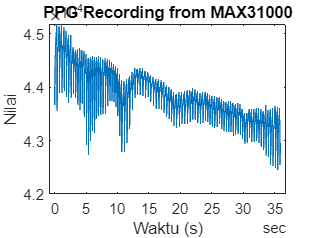

%%Inisialisasi
Fs = 100;

%Import Data
pohr_data = readtable("Tugas 4.csv");
tt_pohr = table2timetable(pohr_data,"SampleRate",Fs);
tt_pohr = renamevars(tt_pohr,'IR','Value');

%Plot Sinyal Awal
t = tt_pohr.Time;
x = tt_pohr.Value;

plot(t,x);
title('PPG Recording from MAX31000');
xlabel('Waktu (s)');
ylabel('Nilai');

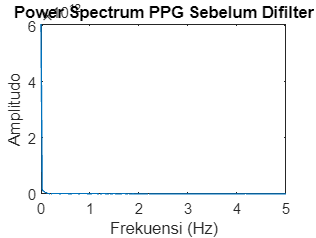

%% Analisis Domain Frekuensi
L = height(t);
n = 2^nextpow2(L); 
xtopi = fft(x,n); 
PSD = (xtopi .* conj(xtopi))/n; %nilai power untuk masing-masing frekuensi
f = (0:n/2) * (Fs/n); %frekuensi 

plot(f,PSD(1:n/2+1));
title('Power Spectrum PPG Sebelum Difilter');
ylabel('Amplitudo');
xlabel('Frekuensi (Hz)');
xlim([0 5]);

%%Desain Filter 
[b, a] = sos2tf(SOS,G);

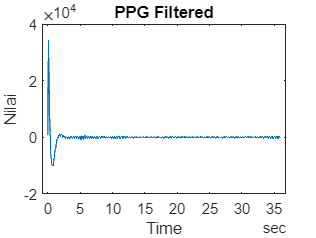

%% Visualisasi yang sudah difilters
x_filtered = filter(b, a, x);

%Plot y yang telah difilini ter 
plot(t,x_filtered);
title('PPG Filtered');
xlabel('Time');
ylabel('Nilai');

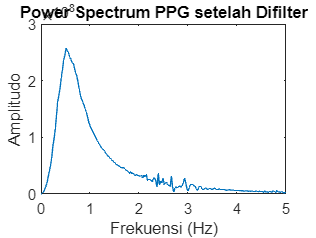

%Plot FFT Y yang telah difilter
X_filtered = fft(x_filtered,n);
PSD_filtered = X_filtered .* conj(X_filtered)/n;

plot(f,PSD_filtered(1:n/2+1));
title('Power Spectrum PPG setelah Difilter');
ylabel('Amplitudo');
xlabel('Frekuensi (Hz)');
xlim([0 5]);